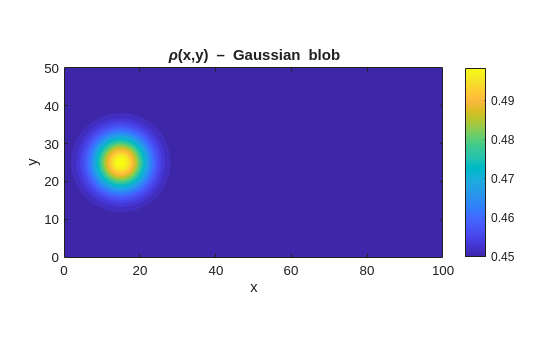

% Grid
global Nx Ny;
Nx = 400; Ny = 200;
Lx = 100; Ly = 50;
dx = Lx / Nx; dy = Ly / Ny;

h = 0;
if dx == dy
    h = dx;
end

x = linspace(0, Lx, Nx);
y = linspace(0, Ly, Ny);

[X, Y] = meshgrid(x, y);

INFINITE = 10^12;
eta = 10^-6;

% To track the error for each iterations
iteration_error = [];
% Center of the blob
x0 = 10;
y0 = 25;
CFL = 0.5;


% Initial Condition (Gaussian Blob)
xc = 15;
yc = 25;
sigma = 5;
rho_gauss = 0.05*exp( -((X-xc).^2 + (Y-yc).^2) / (2*sigma^2) ) + 0.45;

% Lets say there is no obstacle on the way
obstacle = false(Ny, Nx);

% obstacle(80:120,200:240) = true;
rho_gauss(obstacle) = 0;
figure(1); clf
contourf(X, Y, rho_gauss, 30, 'LineColor', 'none');
colorbar
axis equal tight
xlabel('x'); ylabel('y');
title('\rho(x,y) – Gaussian blob');

% Velocity
u = (1 - rho_gauss);
u = max(u, 1e-6);
% Discomfort
g = 0.00 * rho_gauss.^2;
% Cost
c = 1./u + g;
figure(1); clf;
%---------------- Density ----------------%
subplot(2,2,1);
contourf(X, Y, rho_gauss, 30, 'LineColor','none');
colorbar;
axis equal tight;
title('Density \rho(x,y)');
%---------------- Velocity ----------------%
subplot(2,2,2);
contourf(X, Y, u, 30, 'LineColor','none');
colorbar;
axis equal tight;
title('Velocity u(x,y)');
%---------------- Discomfort ----------------%
subplot(2,2,3);
contourf(X, Y, g, 30, 'LineColor','none');

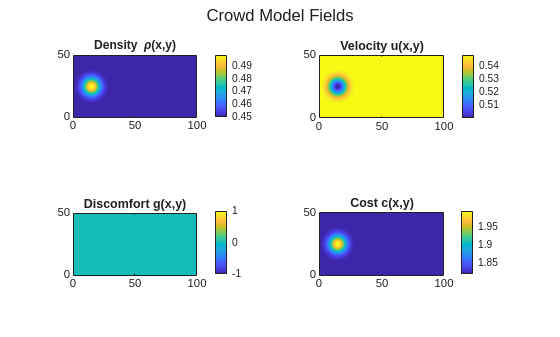

colorbar;
axis equal tight;
title('Discomfort g(x,y)');
%---------------- Cost ----------------%
subplot(2,2,4);
contourf(X, Y, c, 30, 'LineColor','none');
colorbar;
axis equal tight;
title('Cost c(x,y)');
sgtitle('Crowd Model Fields');

% Returns the phi values at the current time step
phi_first_order = First_order_Godunov_Fast_Sweep_Algorithm(c,dx,obstacle,INFINITE);
figure;
contourf(X, Y, phi_first_order, 'LineColor', 'none');
colorbar;
axis equal tight;
title('Potential (First Order Grodunov Fast Sweep Algorithm)');
xlabel('x'); ylabel('y');

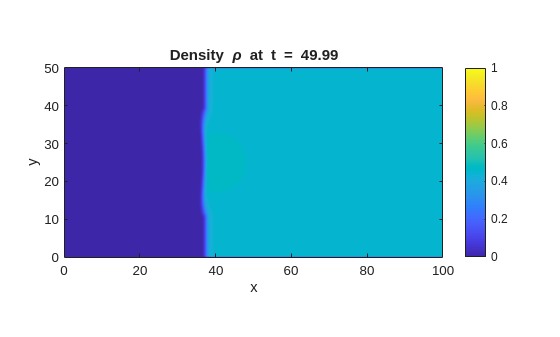

rho = rho_gauss;
dt_i = [];
t_total = 50;
%-----------MAIN SOLVER------------%
t = 0;
step = 0; % For plotting at regular interval
while t< t_total

    % Updating the Spped, Discomfort and Cost
    speed = 1 - rho;
    discomfort = 0.000 * rho.^2;
    cost = 1./speed + discomfort;

    %-- Calculate The final phi using higher ordfer scheme and above intial guess
    phi = First_order_Godunov_Fast_Sweep_Algorithm(cost,h,obstacle,INFINITE);

    %--Calculate the Components of Velocity
    [phi_x, phi_y] = gradient(phi, h, h); % partial derivatives of phi in x and y
    mag_phi = sqrt(phi_x.^2 + phi_y.^2);
    mag_phi = max(mag_phi, eta);

    % To be safe with denominator
    for i = 1:1:Nx
        for j = 1:1:Ny
            x_velocity(j,i) = speed(j,i) * (- phi_x(j,i))/mag_phi(j,i);
            y_velocity(j,i) = speed(j,i) * (- phi_y(j,i))/mag_phi(j,i);
        end
    end

    % Updating the delta_t with proper CFL condition (Wiki Pedia)
    u_max = max(abs(x_velocity(:)));
    v_max = max(abs(y_velocity(:)));
    dt = CFL / ( u_max/h + v_max/h + 1e-12 );

    % Updating the value of rho
    rho = upwind_update(rho, x_velocity, y_velocity, dx, dy, dt);
    step = step+1;
    dt_i(step) = dt;

    %--Ploting the rho_next;
    if mod(step, 10) == 0
        figure(6);
        contourf(x, y, rho, 20, 'LineColor', 'none');
        colorbar;
        clim([0 1]);
        title(sprintf('Density \\rho at t = %.2f', t));
        xlabel('x'); ylabel('y');
        axis equal tight;
        drawnow;
    end

    %fprintf('dt = %0.2f\n',dt);
    % Updating the time
    t = t + dt;
end

dt_i

dt_i =     0.1136    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625


function phi = First_order_Godunov_Fast_Sweep_Algorithm(c,h,obstacle_dash,INFINITE)
    global Nx Ny;
    phi = INFINITE*ones(Ny, Nx);
    phi(:,Nx) = 0;

    for sweep = 1:200
        % === Sweep 1
        for i = 2:Nx-1
            for j = 2:Ny-1
                if ~obstacle_dash(j, i)
                    phi = update_phi(phi, c, i, j, h);
                end
            end
        end
        % === Sweep 2
        for i = Nx-1:-1:2
            for j = 2:Ny-1
                if ~obstacle_dash(j, i)
                    phi = update_phi(phi, c, i, j, h);
                end
            end
        end
        % === Sweep 3
        for i = Nx-1:-1:2
            for j = Ny-1:-1:2
                if ~obstacle_dash(j, i)
                    phi = update_phi(phi, c, i, j, h);
                end
            end
        end
        % === Sweep 4
        for i = 2:Nx-1
            for j = Ny-1:-1:2
                if ~obstacle_dash(j, i)
                    phi = update_phi(phi, c, i, j, h);
                end
            end
        end

        phi(:,1) = phi(:,2);
        phi(:,Nx) = 0;
        phi(1, :) = phi(2, :);
        phi(Ny, :) = phi(Ny-1,:);
    end
end

% Subfunction: Update one grid point using Godunov scheme
function phi = update_phi(phi, c, i, j, dx)
    a = min(phi(j, i-1), phi(j, i+1));  % x-direction neighbors
    b = min(phi(j-1, i), phi(j+1, i));  % y-direction neighbors
    c_i = c(j, i);                      % Local inverse speed
    if abs(a - b) >= c_i * dx
        phi(j, i) = min(a, b) + c_i * dx;
    else
        inside = 2 * (c_i * dx)^2 - (a - b)^2;
        if inside >= 0
            phi(j, i) = (a + b + sqrt(inside)) / 2;
        end
    end
end

function rho_new = upwind_update(rho, vx, vy, dx, dy, dt)
    global Nx Ny;
    % Boundary Condition
    for j = 2 : Ny-1
        rho(j,1) = 0;
        rho(j,Nx) = rho(j,Nx-1);
    end
    for i = 2 : Nx-1
        rho(1,i) = 0;
        rho(Ny,i) = 0;
    end
    % Initalizing the flux values to be zero intially.
    flux_xp = zeros(Ny,Nx);
    flux_xm = zeros(Ny,Nx);
    flux_yp = zeros(Ny,Nx);
    flux_ym = zeros(Ny,Nx);
    % Upwinding scheme implementation
    for j = 2 : Ny-1
        for i = 2 : Nx-1
            % x-direction fluxes
            flux_xp(j,i) = max(vx(j,i),0)*rho(j,i)+min(vx(j,i),0)*rho(j,i+1);
            flux_xm(j,i) = max(vx(j,i),0)*rho(j,i-1) +min(vx(j,i),0)*rho(j,i);
            % y-direction fluxes
            flux_yp(j,i) = max(vy(j,i),0)*rho(j,i) + min(vy(j,i),0)*rho(j+1,i);
            flux_ym(j,i) = max(vy(j,i),0)*rho(j-1,i) + min(vy(j,i),0)*rho(j,i);
        end
    end
    % Finite difference equation obtained form discritization of continuity equation.
    rho_new = rho - (dt/dx) * (flux_xp - flux_xm) - (dt/dy) * (flux_yp - flux_ym);
end